## **Generating scatter plots of several network connections that shoed significant differences between groups 2 and 4, FDR corrected**

% Networks that we want to look at:
%  (39,112)     0.0664
%  (75,122)     0.1956
%  (120,133)     0.2014
%  (120,169)     0.2503
%  (139,169)     0.0780
%  (148,169)     0.1932
%  (97,175)     0.2573
%  (139,180)     0.2759


%%%%%%%%
%%  MAKE SURE YOU RUN THIS INSIDE THE Box_scatter_plots FOLDER 
%%%%%%%

%%% %%
%%% need to download the function CategoricalScatterplot from here:
%%% https://github.com/AbstractGeek/CategoricalScatterplot
%%%%

% Scatter plot 

clear all
close all

subjs1 = {'sub-1001_ses-01.Schaefer200_CORR_Z_tsv.txt', 'sub-1003_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-1004_ses-01.Schaefer200_CORR_Z_tsv.txt', 'sub-1006_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-1007_ses-01.Schaefer200_CORR_Z_tsv.txt', 'sub-1009_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-1010_ses-01.Schaefer200_CORR_Z_tsv.txt', 'sub-1011_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-1012_ses-01.Schaefer200_CORR_Z_tsv.txt', 'sub-1013_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-1014_ses-01.Schaefer200_CORR_Z_tsv.txt', 'sub-1015_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-1016_ses-01.Schaefer200_CORR_Z_tsv.txt', 'sub-1017_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-1018_ses-01.Schaefer200_CORR_Z_tsv.txt', 'sub-1019_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-1020_ses-01.Schaefer200_CORR_Z_tsv.txt', 'sub-1021_ses-01.Schaefer200_CORR_Z_tsv.txt'}

subjs1 = 1×18 cell array
    {'sub-1001_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1003_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1004_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1006_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1007_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1009_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1010_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1011_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1012_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1013_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1014_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1015_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1016_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1017_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1018_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1019_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1020_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-1021_ses-01.Schaefer200_CORR_Z_tsv.txt'}




% removed 2007
subjs2 = {'sub-2002_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2003_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2004_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2005_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2006_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2007_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2008_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2010_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2011_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2012_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2013_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2014_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2015_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2016_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2017_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2018_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2020_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-2021_ses-01.Schaefer200_CORR_Z_tsv.txt'}

subjs2 = 1×18 cell array
    {'sub-2002_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2003_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2004_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2005_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2006_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2007_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2008_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2010_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2011_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2012_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2013_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2014_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2015_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2016_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2017_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2018_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2020_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-2021_ses-01.Schaefer200_CORR_Z_tsv.txt'}




subjs4 = {'sub-4001_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4002_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4003_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4004_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4005_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4006_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4007_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4009_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4010_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4012_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4013_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4014_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4015_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4016_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4017_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4018_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4020_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4021_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4022_ses-01.Schaefer200_CORR_Z_tsv.txt', ...
'sub-4023_ses-01.Schaefer200_CORR_Z_tsv.txt'}

subjs4 = 1×20 cell array
    {'sub-4001_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4002_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4003_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4004_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4005_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4006_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4007_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4009_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4010_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4012_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4013_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4014_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4015_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4016_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4017_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4018_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4020_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4021_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4022_ses-01.Schaefer200_CORR_Z_tsv.txt'}    {'sub-4023_ses-01.Sch

## Load Tables

% this is the folder with the smith network correlations
folder = '../correlations_tsv_z/';
% Group 1
tables_1 = [];
for ii = 1:length(subjs1)
    %tables_1(:,:,ii) = dlmread([folder subjs1{ii} '.Network_CORR_Z_tsv.txt']); 
    %ls [folder subjs1{ii}]
    tables_1(:,:,ii) = dlmread([folder subjs1{ii} ]);
end

% Group 2
tables_2 = [];
for ii = 1:length(subjs2)
    %tables_2(:,:,ii) = dlmread([folder subjs2{ii} '.Network_CORR_Z_tsv.txt']); 
    tables_2(:,:,ii) = dlmread([folder subjs2{ii} ]);
end

% Group 4
tables_4 = [];
for ii = 1:length(subjs4)
    %tables_4(:,:,ii) = dlmread([folder subjs4{ii} '.Network_CORR_Z_tsv.txt']); 
    tables_4(:,:,ii) = dlmread([folder subjs4{ii} ]); 
end




## Schaefer  (39,112)     

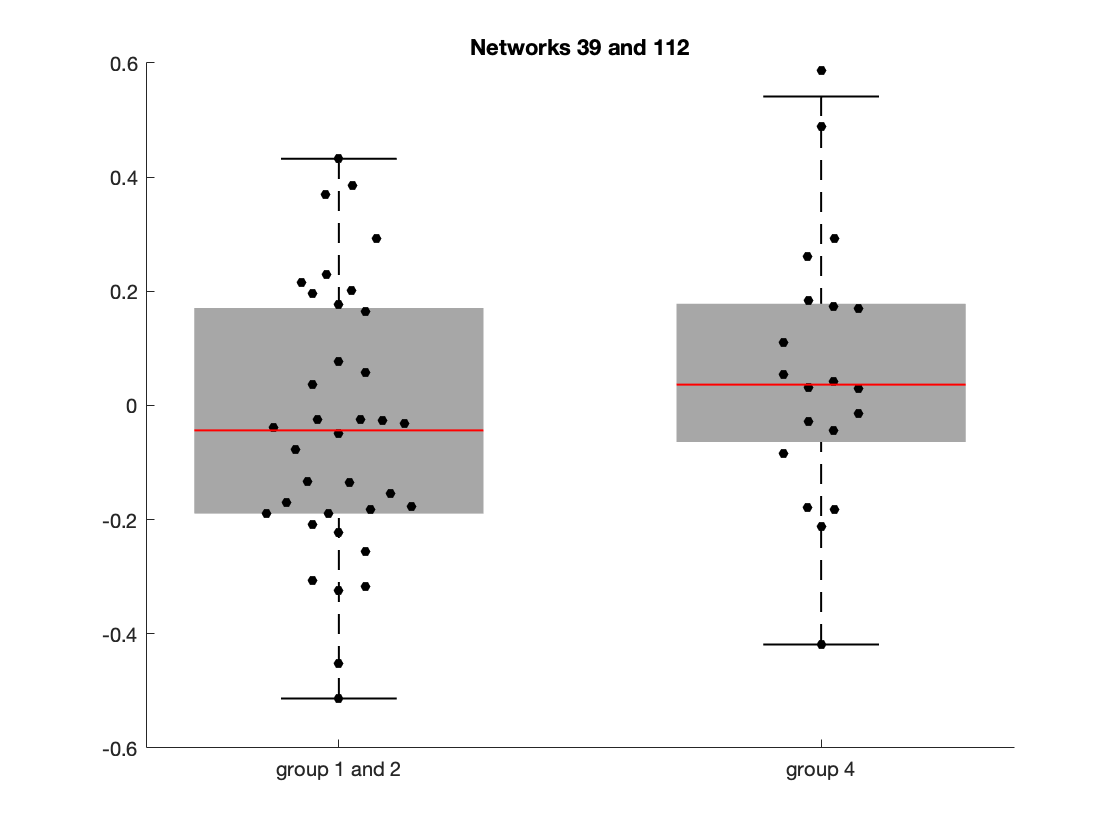

%  (39,112)     0.0664

% ROIS
x = 39;
y = 112;


group1_2 = [squeeze(tables_1(x,y,:)) ; squeeze(tables_2(x,y,:))];
group4 = squeeze(tables_4(x,y,:));
group1 = squeeze(tables_1(x,y,:));
group2 = squeeze(tables_2(x,y,:));

% 1 and 2 vs 4
label_g1and2{1} = ['group 1 and 2'];
label_g4{1} = 'group 4';
 
labels_all = [repmat(label_g1and2,length(group1_2),1) ; repmat(label_g4,length(group4),1)];
data_in = [group1_2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )

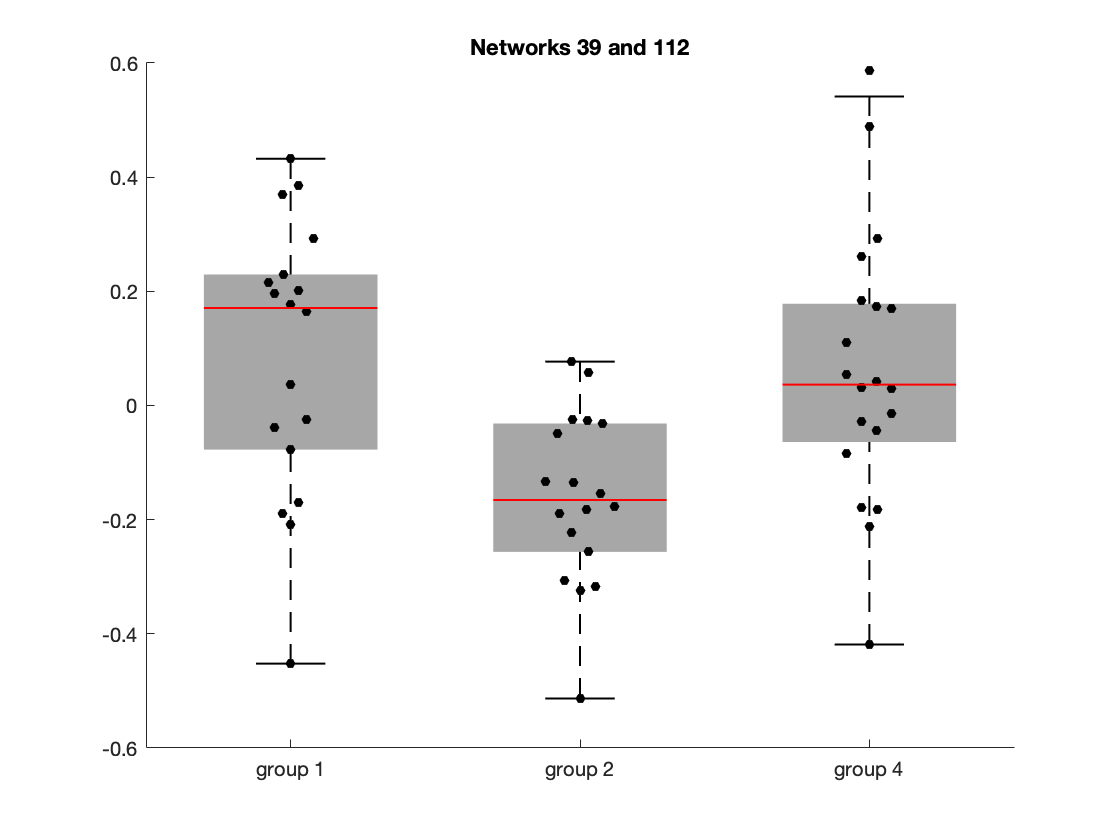


% Now a figure separating all 3 groups
label_g1{1} = ['group 1'];
label_g2{1} = ['group 2'];


labels_all = [repmat(label_g1,length(group1),1); ...
    repmat(label_g2,length(group2),1); ...
    repmat(label_g4,length(group4),1)];
data_in = [group1; group2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )


[H,P] = ttest2(group2,group4)

H = 1

P = 0.0015

## Schaefer  (75,122)     

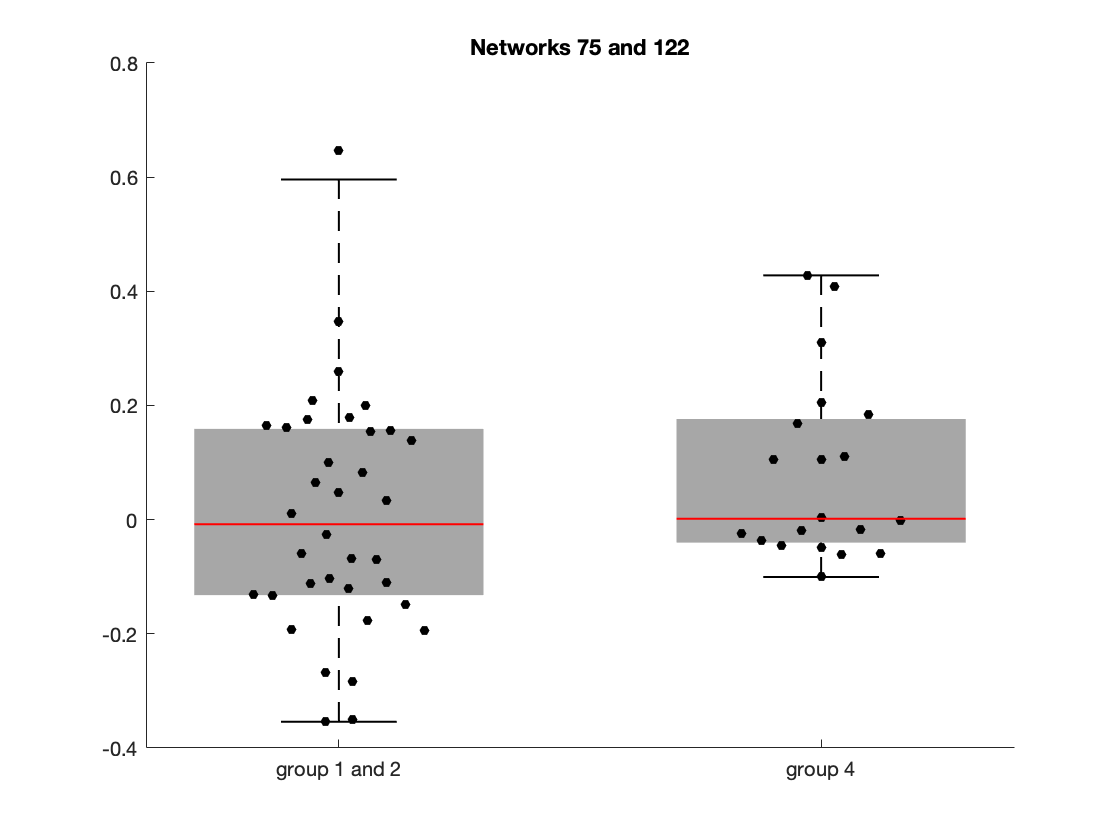

%  (75,122)     0.1956

% ROIS
x = 75;
y = 122;

group1_2 = [squeeze(tables_1(x,y,:)) ; squeeze(tables_2(x,y,:))];
group4 = squeeze(tables_4(x,y,:));
group1 = squeeze(tables_1(x,y,:));
group2 = squeeze(tables_2(x,y,:));

% 1 and 2 vs 4
label_g1and2{1} = ['group 1 and 2'];
label_g4{1} = 'group 4';
 
labels_all = [repmat(label_g1and2,length(group1_2),1) ; repmat(label_g4,length(group4),1)];
data_in = [group1_2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )

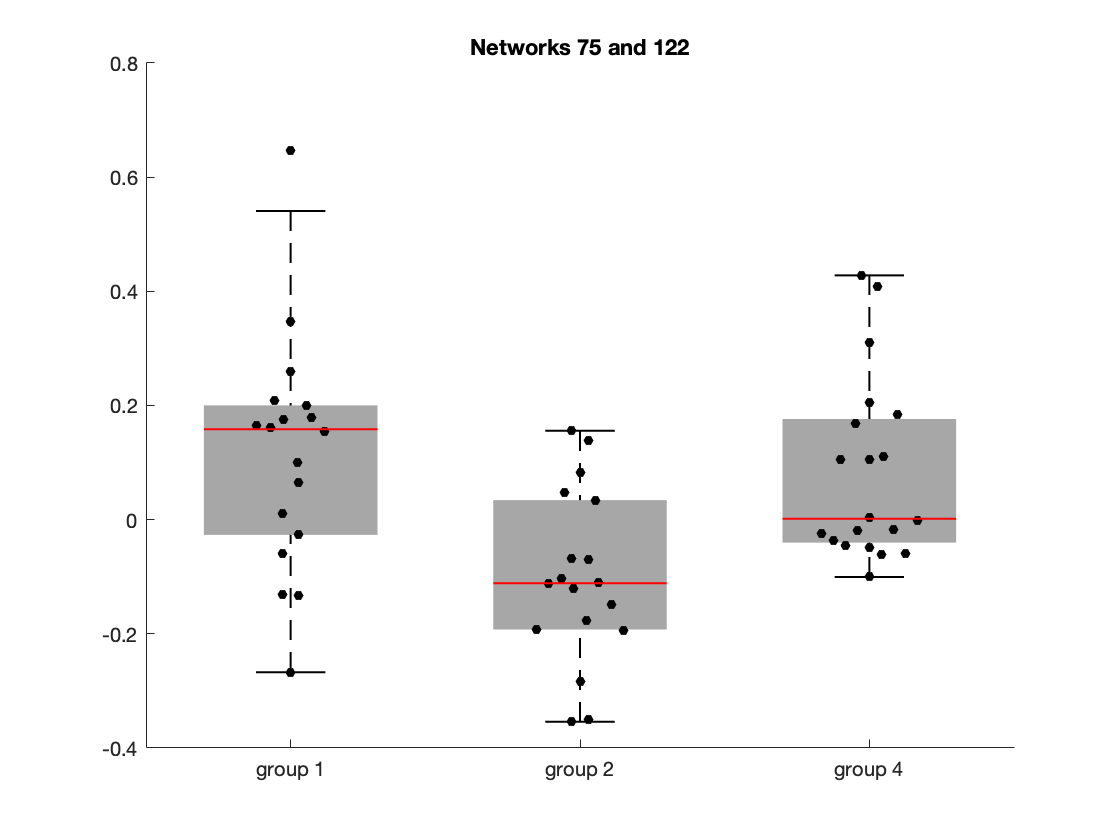


% Now a figure separating all 3 groups
label_g1{1} = ['group 1'];
label_g2{1} = ['group 2'];

labels_all = [repmat(label_g1,length(group1),1); ...
    repmat(label_g2,length(group2),1); ...
    repmat(label_g4,length(group4),1)];
data_in = [group1; group2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )


[H,P] = ttest2(group2,group4)

H = 1

P = 8.8138e-04

## Schaefer  (120,133)     

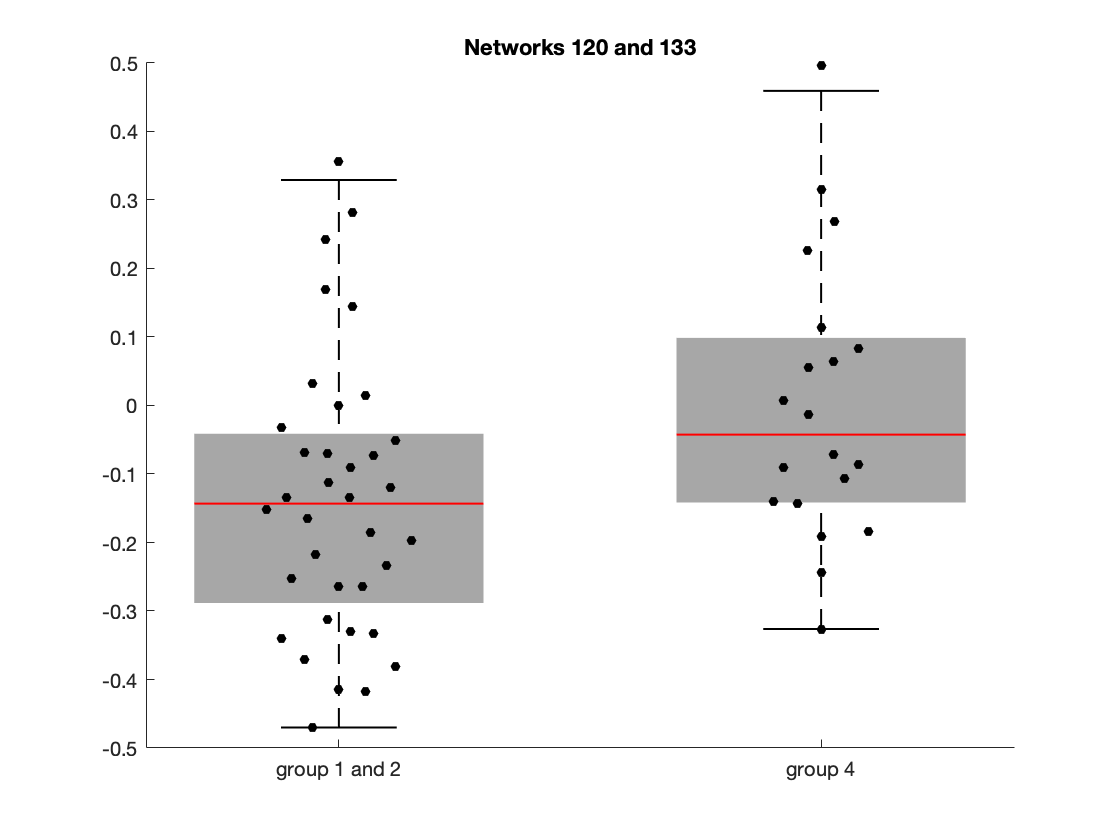

%  (120,133)     0.2014

% ROIS
x = 120;
y = 133;

group1_2 = [squeeze(tables_1(x,y,:)) ; squeeze(tables_2(x,y,:))];
group4 = squeeze(tables_4(x,y,:));
group1 = squeeze(tables_1(x,y,:));
group2 = squeeze(tables_2(x,y,:));

% 1 and 2 vs 4
label_g1and2{1} = ['group 1 and 2'];
label_g4{1} = 'group 4';
 
labels_all = [repmat(label_g1and2,length(group1_2),1) ; repmat(label_g4,length(group4),1)];
data_in = [group1_2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )

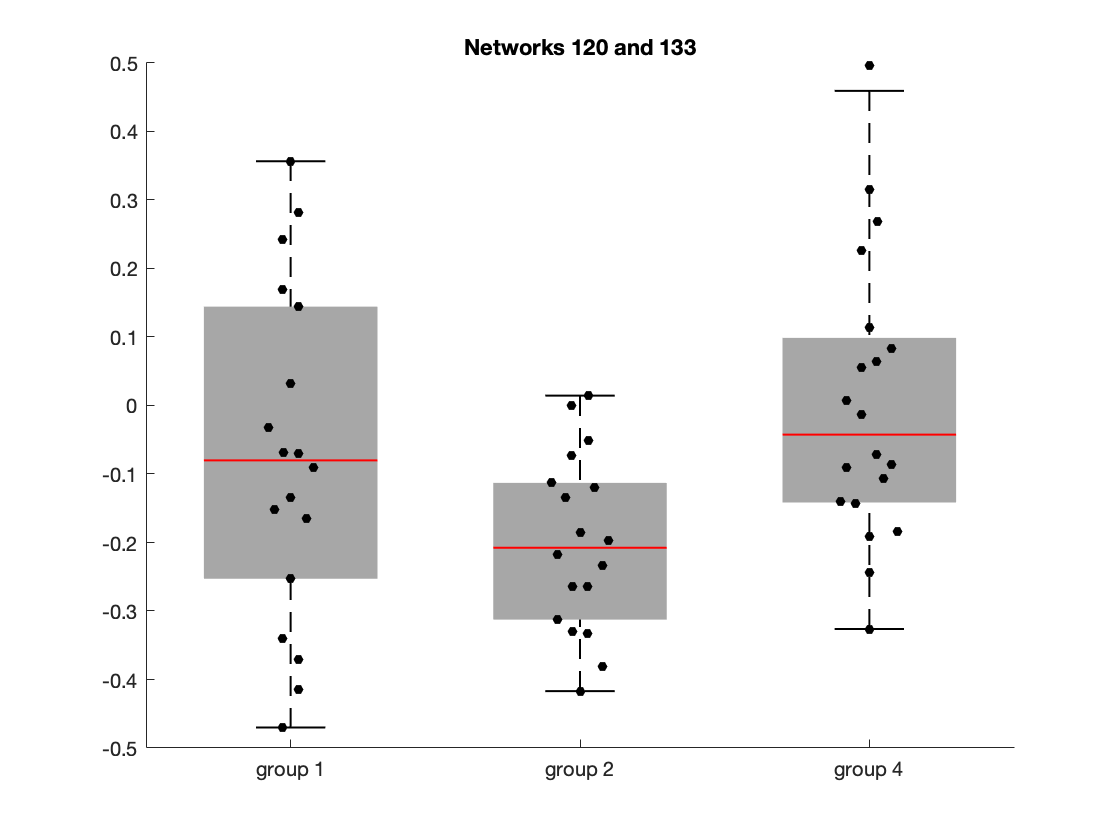


% Now a figure separating all 3 groups
label_g1{1} = ['group 1'];
label_g2{1} = ['group 2'];

labels_all = [repmat(label_g1,length(group1),1); ...
    repmat(label_g2,length(group2),1); ...
    repmat(label_g4,length(group4),1)];
data_in = [group1; group2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )


[H,P] = ttest2(group2,group4)

H = 1

P = 9.8900e-04

## Schaefer  (120,169)     

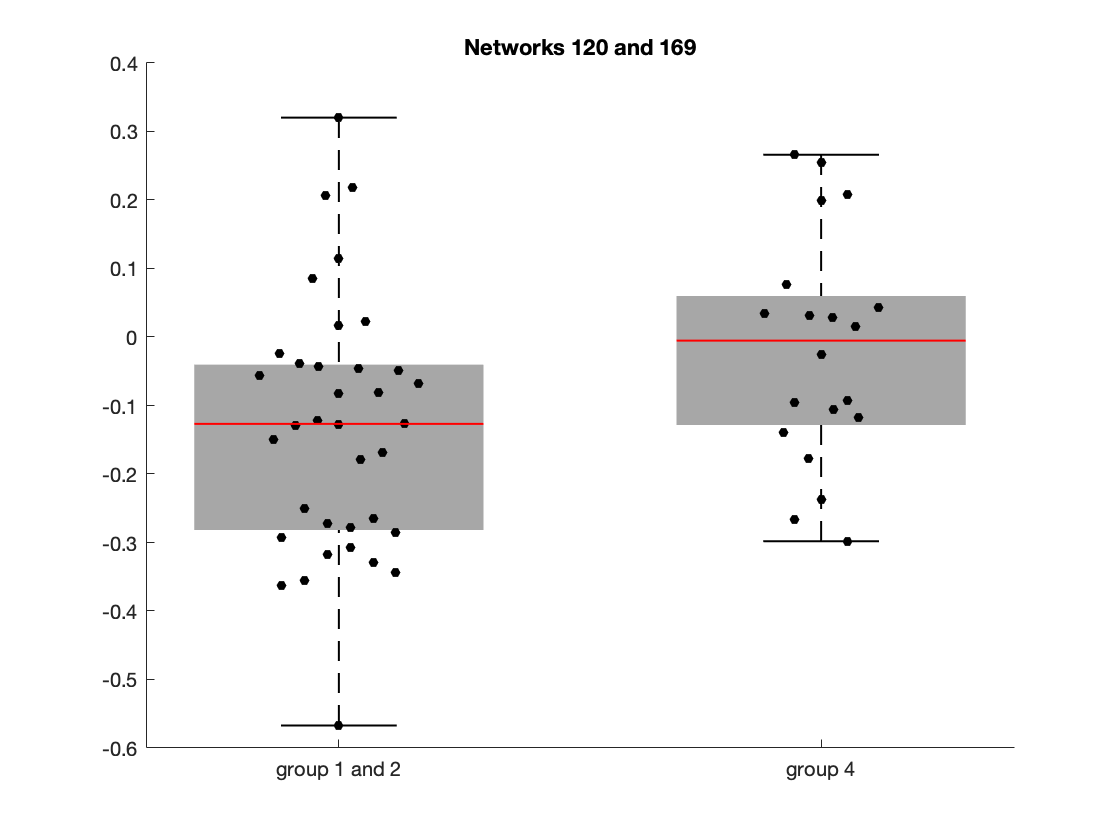

%  (120,169)     0.2503

% ROIS
x = 120;
y = 169;

group1_2 = [squeeze(tables_1(x,y,:)) ; squeeze(tables_2(x,y,:))];
group4 = squeeze(tables_4(x,y,:));
group1 = squeeze(tables_1(x,y,:));
group2 = squeeze(tables_2(x,y,:));

% 1 and 2 vs 4
label_g1and2{1} = ['group 1 and 2'];
label_g4{1} = 'group 4';
 
labels_all = [repmat(label_g1and2,length(group1_2),1) ; repmat(label_g4,length(group4),1)];
data_in = [group1_2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )

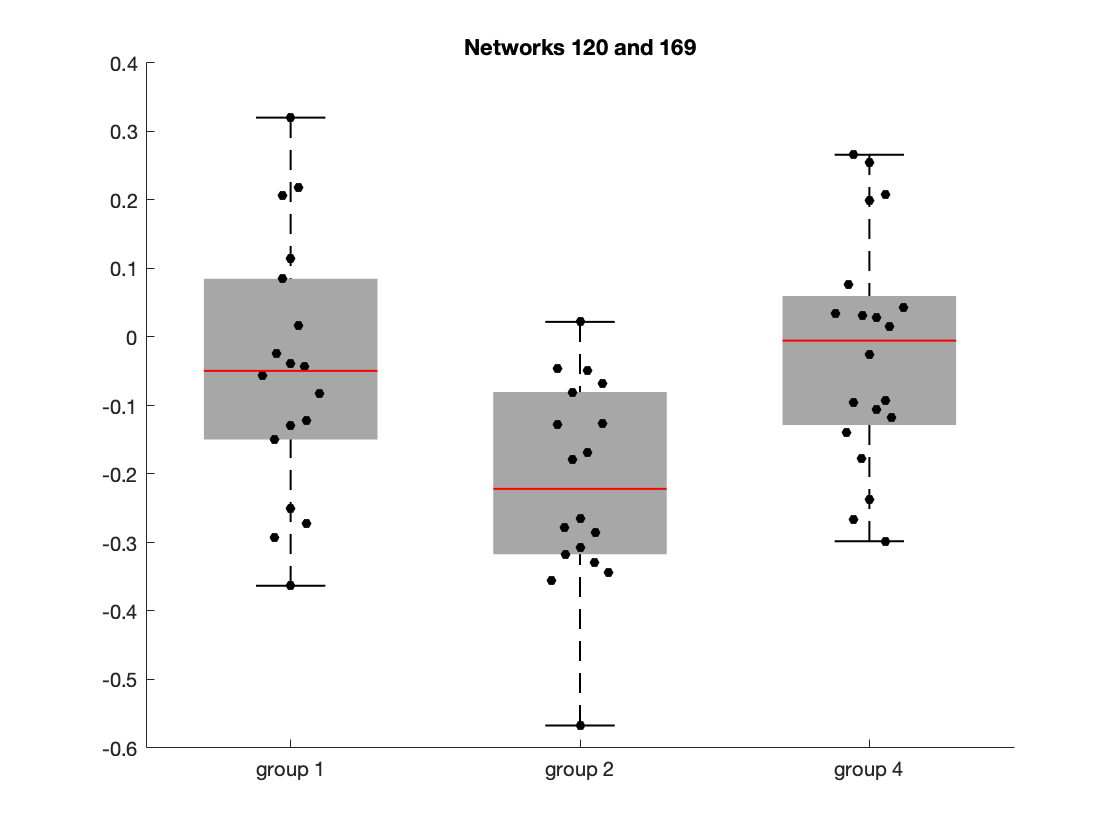


% Now a figure separating all 3 groups
label_g1{1} = ['group 1'];
label_g2{1} = ['group 2'];

labels_all = [repmat(label_g1,length(group1),1); ...
    repmat(label_g2,length(group2),1); ...
    repmat(label_g4,length(group4),1)];
data_in = [group1; group2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )


[H,P] = ttest2(group2,group4)

H = 1

P = 5.6242e-04

## Schaefer  (139,169)     

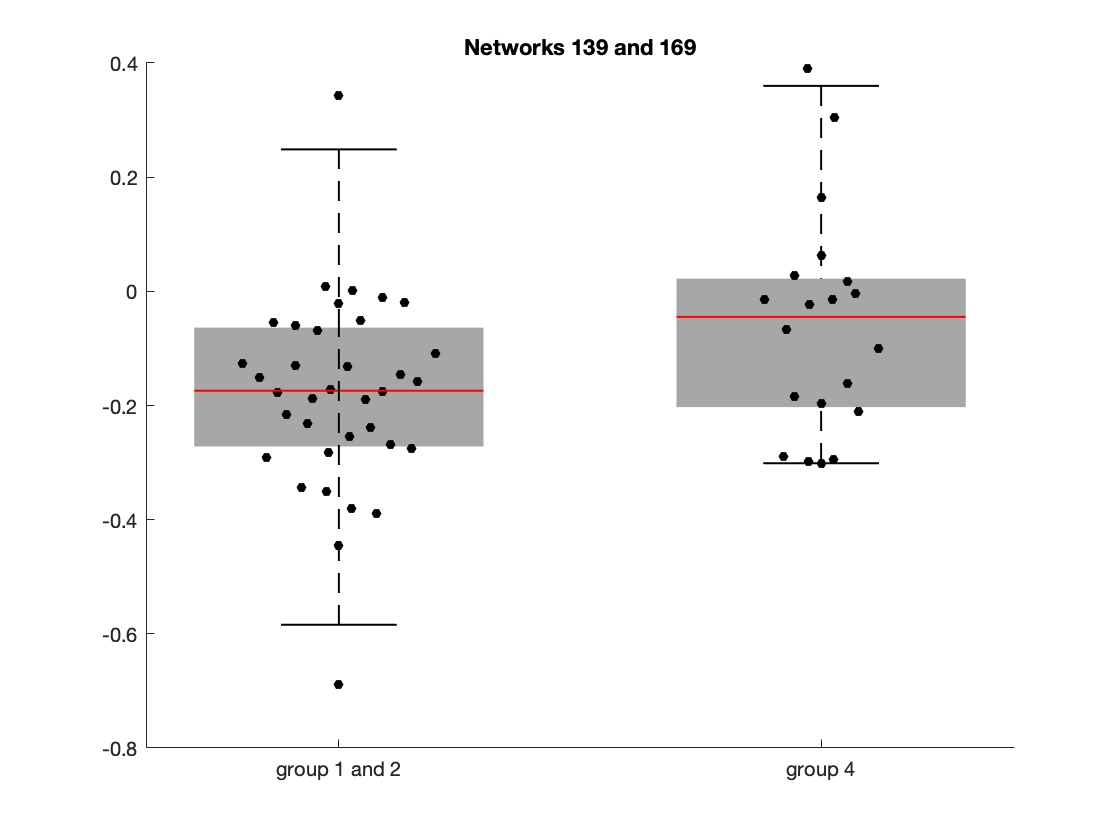

%  (139,169)     0.0780

% ROIS
x = 139;
y = 169;

group1_2 = [squeeze(tables_1(x,y,:)) ; squeeze(tables_2(x,y,:))];
group4 = squeeze(tables_4(x,y,:));
group1 = squeeze(tables_1(x,y,:));
group2 = squeeze(tables_2(x,y,:));

% 1 and 2 vs 4
label_g1and2{1} = ['group 1 and 2'];
label_g4{1} = 'group 4';
 
labels_all = [repmat(label_g1and2,length(group1_2),1) ; repmat(label_g4,length(group4),1)];
data_in = [group1_2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )

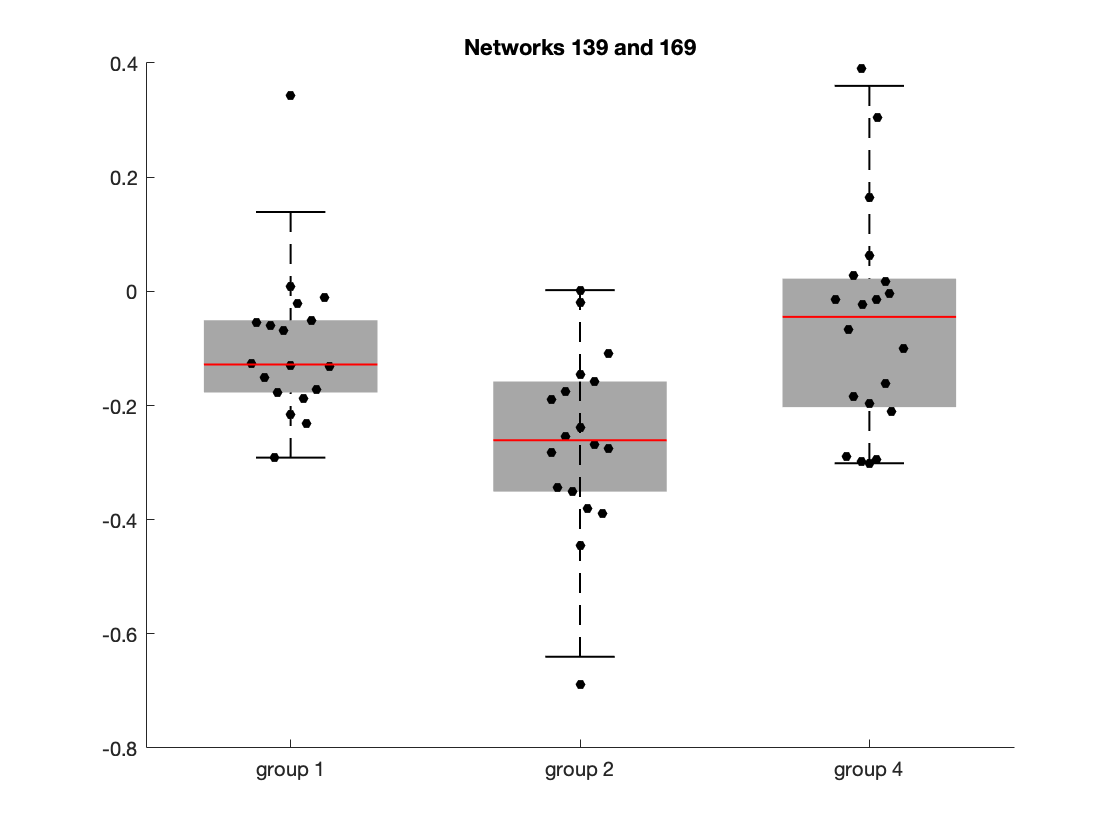


% Now a figure separating all 3 groups
label_g1{1} = ['group 1'];
label_g2{1} = ['group 2'];

labels_all = [repmat(label_g1,length(group1),1); ...
    repmat(label_g2,length(group2),1); ...
    repmat(label_g4,length(group4),1)];
data_in = [group1; group2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )


[H,P] = ttest2(group2,group4)

H = 1

P = 0.0014

## Schaefer  (148,169)   

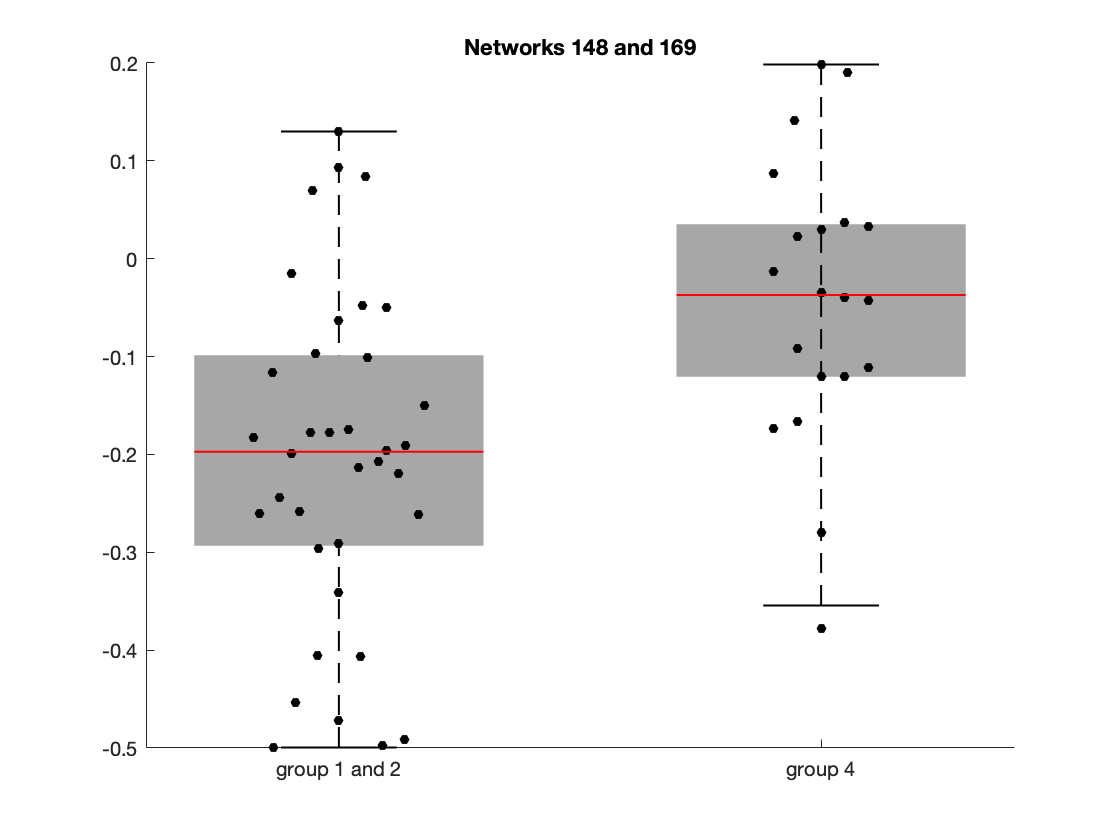

%  (148,169)     0.1932

% ROIS
x = 148;
y = 169;

group1_2 = [squeeze(tables_1(x,y,:)) ; squeeze(tables_2(x,y,:))];
group4 = squeeze(tables_4(x,y,:));
group1 = squeeze(tables_1(x,y,:));
group2 = squeeze(tables_2(x,y,:));

% 1 and 2 vs 4
label_g1and2{1} = ['group 1 and 2'];
label_g4{1} = 'group 4';
 
labels_all = [repmat(label_g1and2,length(group1_2),1) ; repmat(label_g4,length(group4),1)];
data_in = [group1_2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )

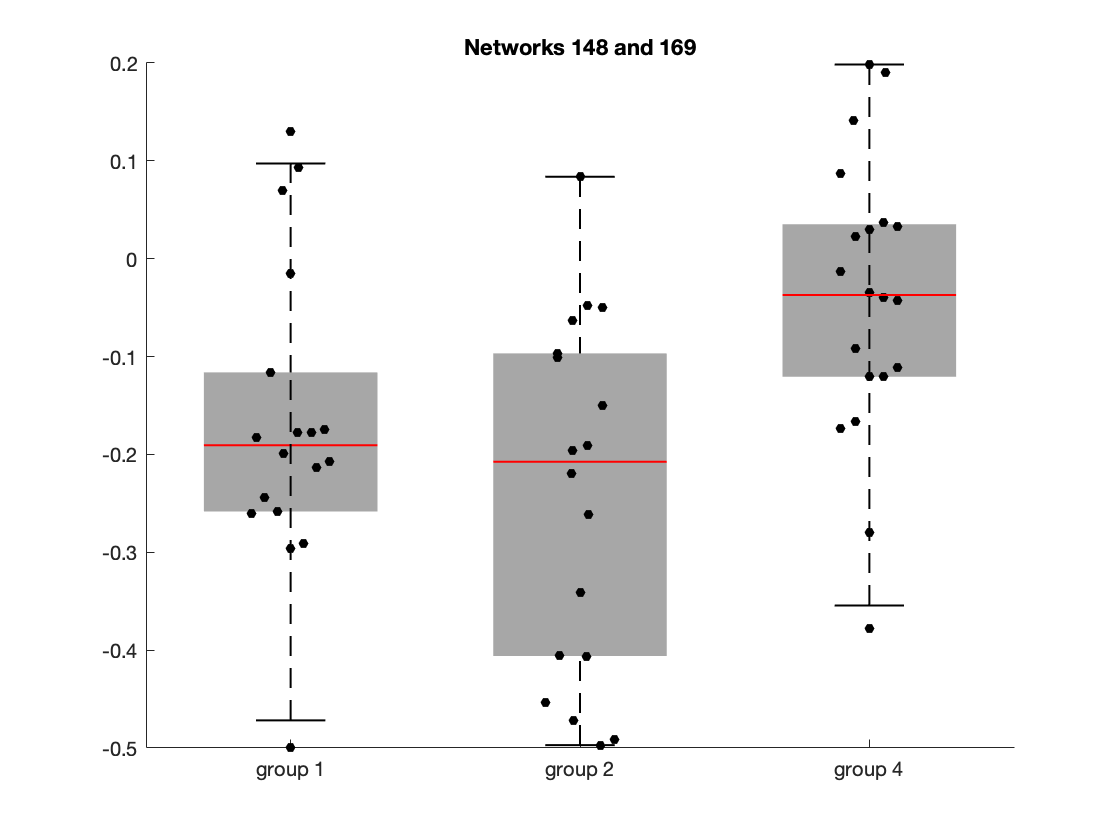


% Now a figure separating all 3 groups
label_g1{1} = ['group 1'];
label_g2{1} = ['group 2'];

labels_all = [repmat(label_g1,length(group1),1); ...
    repmat(label_g2,length(group2),1); ...
    repmat(label_g4,length(group4),1)];
data_in = [group1; group2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )


[H,P] = ttest2(group2,group4)

H = 1

P = 5.7818e-04

## Schaefer  (97,175)  

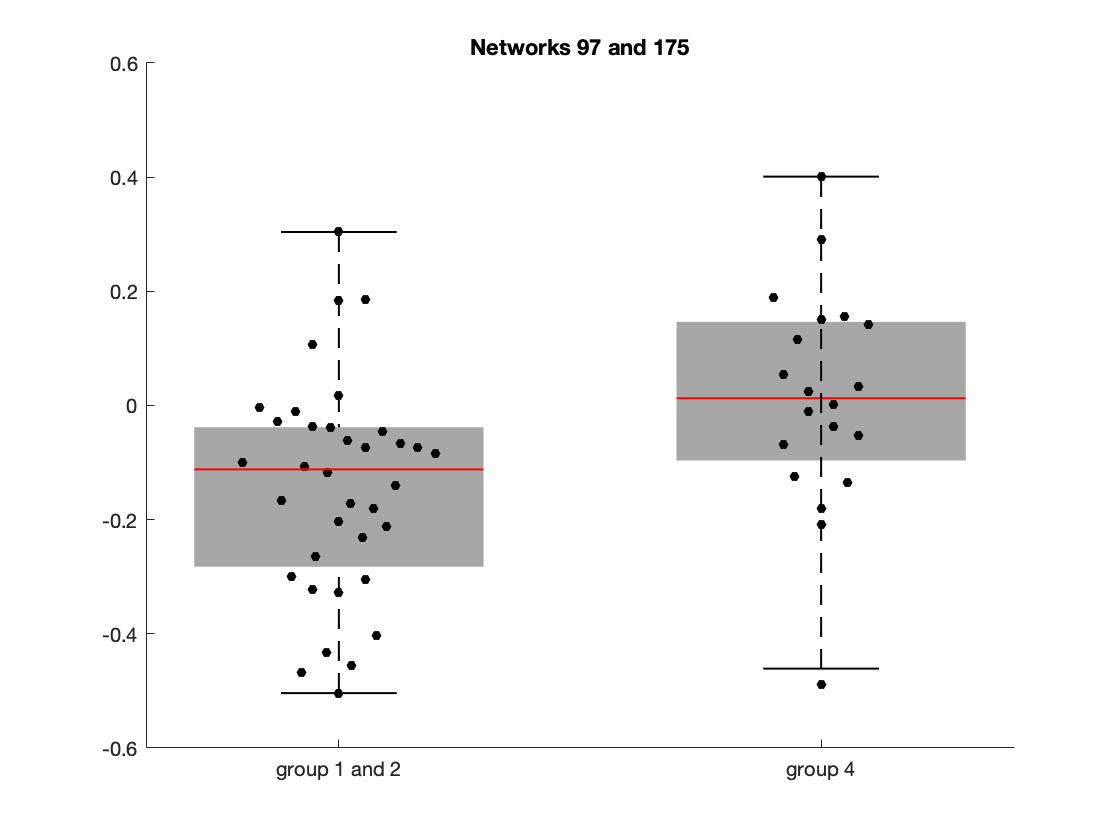

%  (97,175)     0.2573

% ROIS
x = 97;
y = 175;

group1_2 = [squeeze(tables_1(x,y,:)) ; squeeze(tables_2(x,y,:))];
group4 = squeeze(tables_4(x,y,:));
group1 = squeeze(tables_1(x,y,:));
group2 = squeeze(tables_2(x,y,:));

% 1 and 2 vs 4
label_g1and2{1} = ['group 1 and 2'];
label_g4{1} = 'group 4';
 
labels_all = [repmat(label_g1and2,length(group1_2),1) ; repmat(label_g4,length(group4),1)];
data_in = [group1_2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )

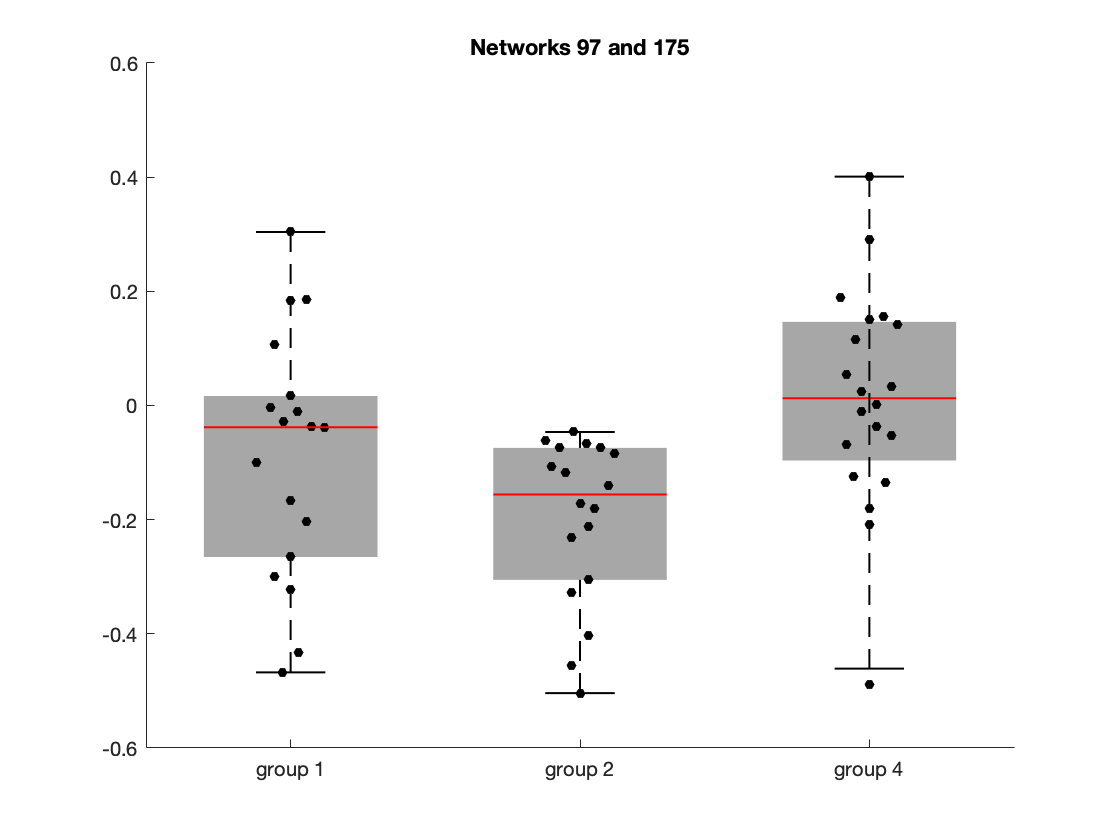


% Now a figure separating all 3 groups
label_g1{1} = ['group 1'];
label_g2{1} = ['group 2'];

labels_all = [repmat(label_g1,length(group1),1); ...
    repmat(label_g2,length(group2),1); ...
    repmat(label_g4,length(group4),1)];
data_in = [group1; group2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )



[H,P] = ttest2(group2,group4)

H = 1

P = 6.1520e-04

## Schaefer  (139,180)  

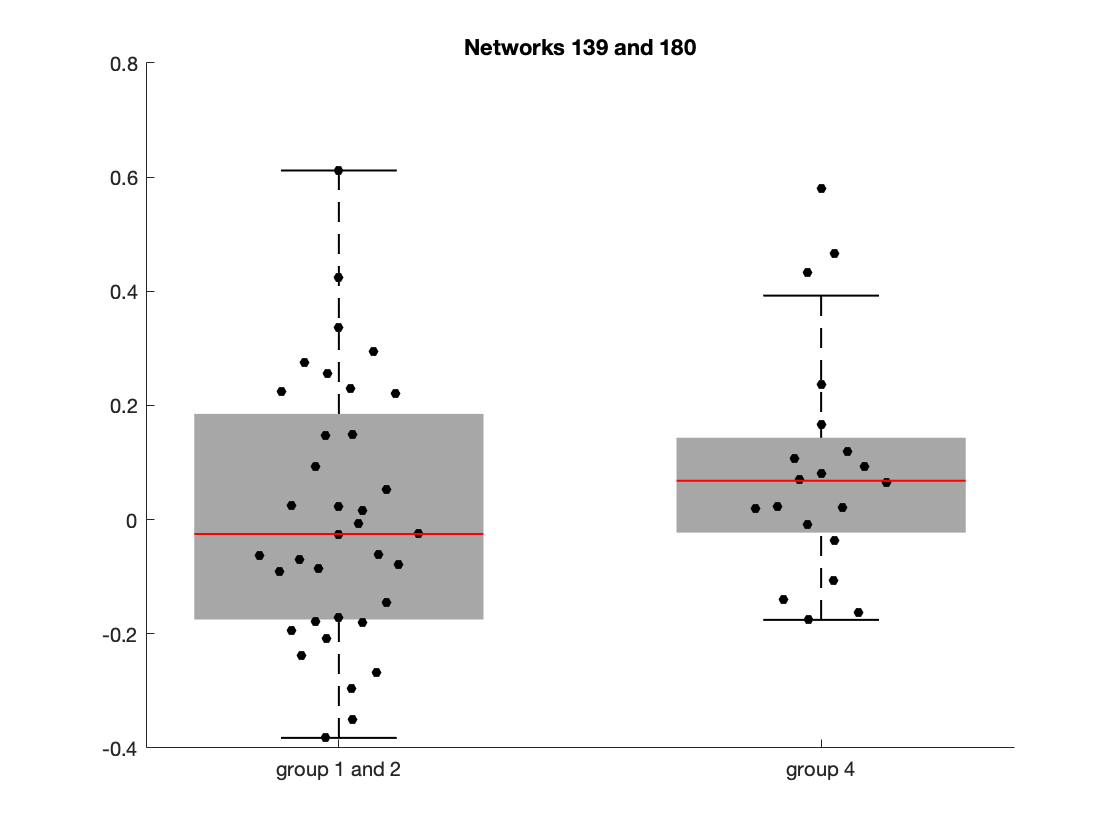

%  (139,180)     0.2759

% ROIS
x = 139;
y = 180;

group1_2 = [squeeze(tables_1(x,y,:)) ; squeeze(tables_2(x,y,:))];
group4 = squeeze(tables_4(x,y,:));
group1 = squeeze(tables_1(x,y,:));
group2 = squeeze(tables_2(x,y,:));

% 1 and 2 vs 4
label_g1and2{1} = ['group 1 and 2'];
label_g4{1} = 'group 4';
 
labels_all = [repmat(label_g1and2,length(group1_2),1) ; repmat(label_g4,length(group4),1)];
data_in = [group1_2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )

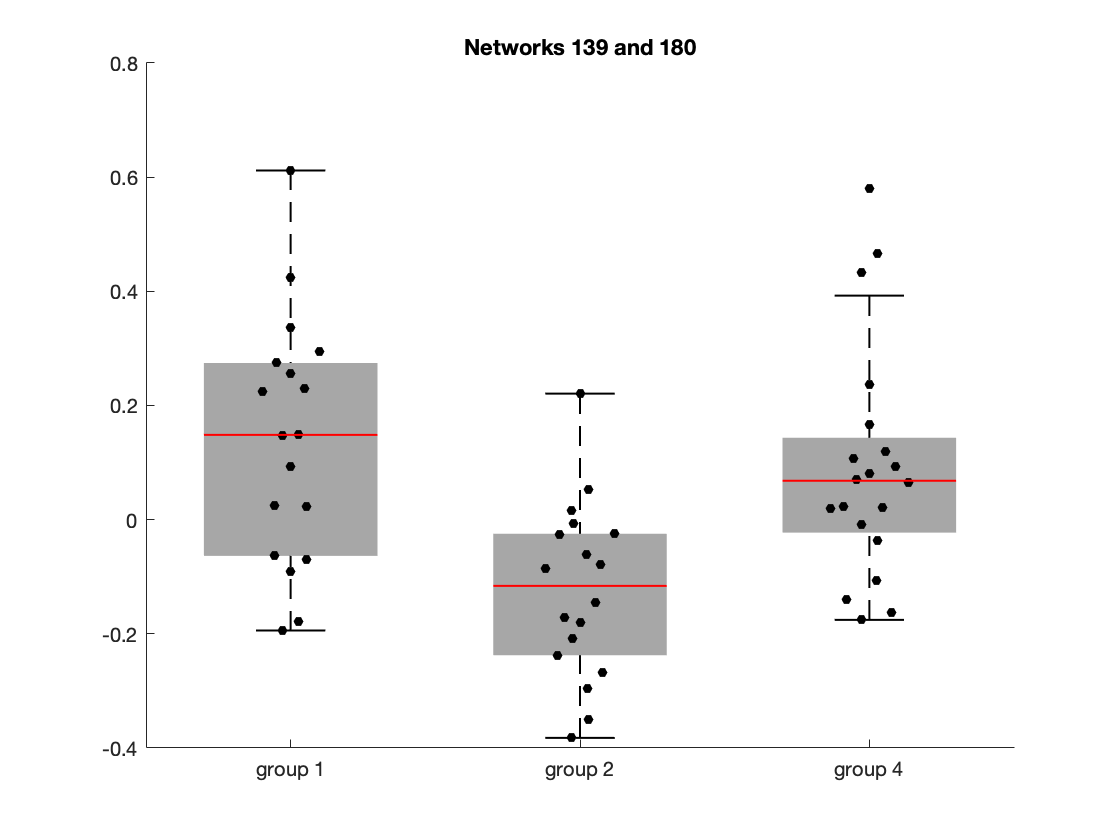


% Now a figure separating all 3 groups
label_g1{1} = ['group 1'];
label_g2{1} = ['group 2'];

labels_all = [repmat(label_g1,length(group1),1); ...
    repmat(label_g2,length(group2),1); ...
    repmat(label_g4,length(group4),1)];
data_in = [group1; group2 ; group4];

figure
CategoricalScatterplot(data_in,labels_all)
title(['Networks ' num2str(x) ' and ' num2str(y)] )



[H,P] = ttest2(group2,group4)

H = 1

P = 8.2568e-04